# Lab 6: Confidence intervals

## Megan Miyasaki 

Partner: Kuan Lee

**Setup**

**First, we want to have some `background' data (presumably signal free) onto which we can inject a simulated signal. So the first step is to isolate some appropriate data from your data files. **

*Since I am working with the LHC data, below is a code that helps me build a fake poission background with a mean 100. I will use this background throught the report. *

clear;close all;clc;
size = 10000;
mean=100;
background=poissrnd(mean,[1, size]);

## Problem 1

**The first problem is to look at your background distribution and determine where the 5σ sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]**

*I know that 5σ is a 1 in 3.5 million change of an event happening, therefore below is the code of be find the 5σ sensitivity threshold is using matlab code. *

prob5sigma=1/3.5e6;
prob=fitdist(background','Poisson');
sigma_5=icdf(prob,1-prob5sigma);

The code is finding the x-value for where we are 5 sigma away from the mean:


$$\int_X^{\infty } \textrm{pdf}\left(x\right)\textrm{dx}=\frac{1}{3\ldotp 5*{10}^6 };X=154$$
 

From this code we can see that the 5σ sensitivity threshold is 54 from the mean of 100, so it is 154.

The last thing I want to do is see how this distribution looks so I will make a histogram of it below:

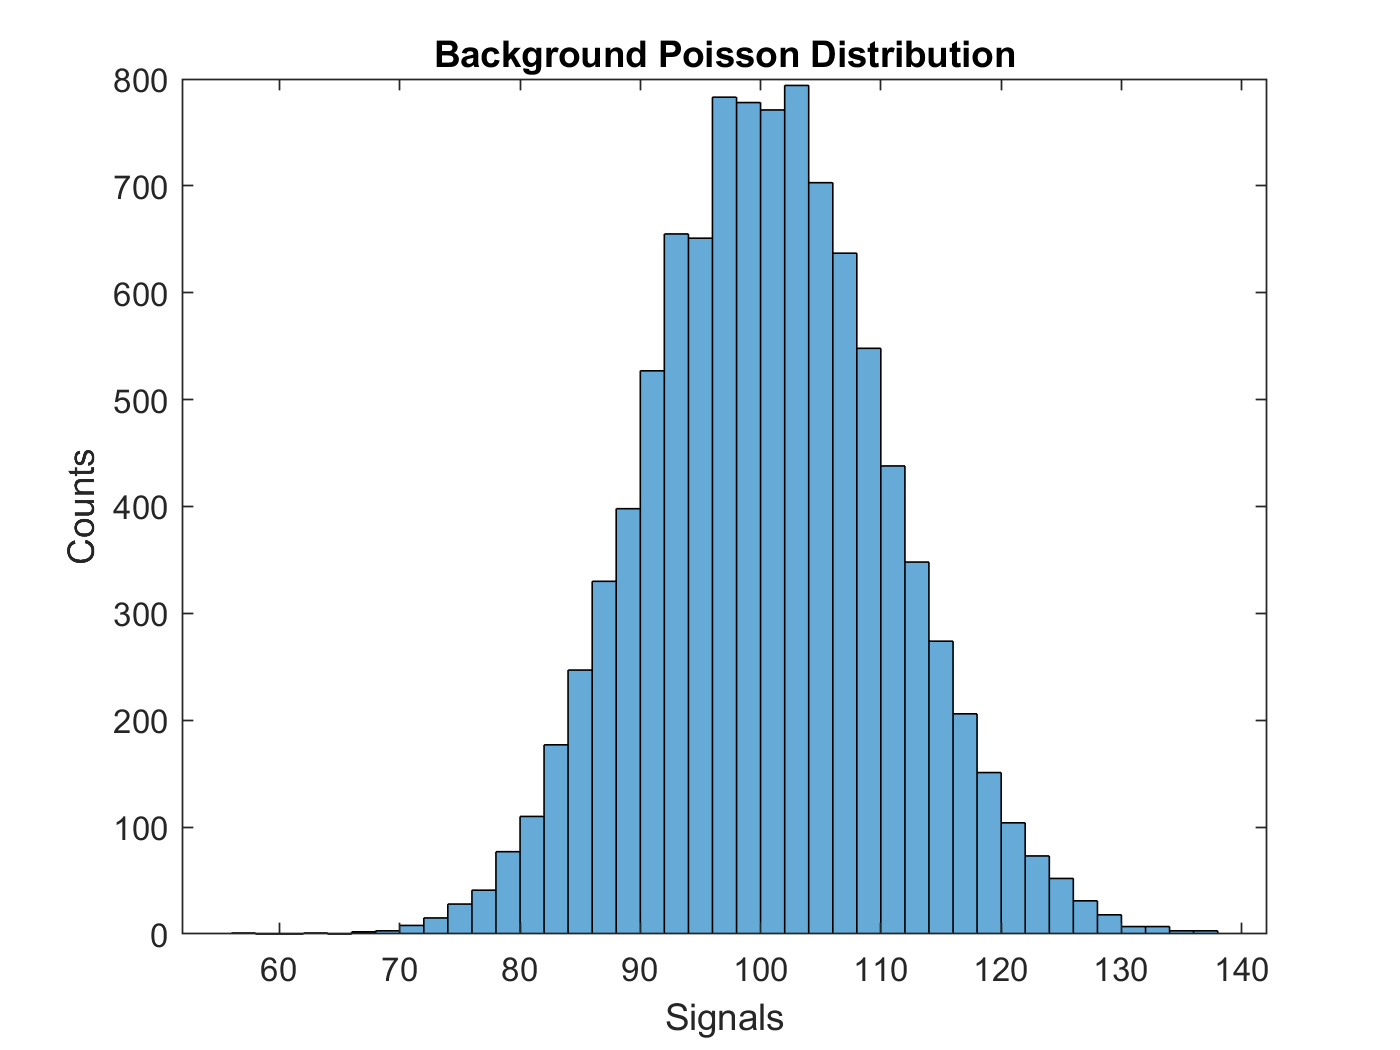

histogram(background);
title('Background Poisson Distribution')
xlabel("Signals")
ylabel("Counts")

From this histogram I can see the background distribution I made as well as the 5 sigma is very far from the mean. 

## Problem 2

**Now create a set of injected (simulated) signals of a *****single strength*****. You will want to make your signal moderately strong, say somewhere in the 8-30σ range. Inject this signal into your background data many times.**

*I will now build injected or simulated signals of a single strength, of a 8-30σ range. *

*In order to find a 8-30σ range, we can use find the probability of 8*$\sigma$on* a gaussian distribution then equate that to what it would be on a Poission*

prob8sigma=1-normcdf(8);
prob30sigma=1-normcdf(30);
prob9sigma=1-normcdf(9);

Note how that the probability cannot be found at 9$\sigma$ due to matlabs percision, therefore 30$\sigma$ would be incredible hard to find since 8$\sigma$ is already so small, therefore I will just focus for my interjected signals to be sigma to be 8$\sigma$.

sigma_8=icdf(prob,1-prob8sigma);

From here we see that 8$\sigma$ is 90 away from the mean of 100, so it is 190.

**a) Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.**

*I wil inject 1000 signals of strength 190.*

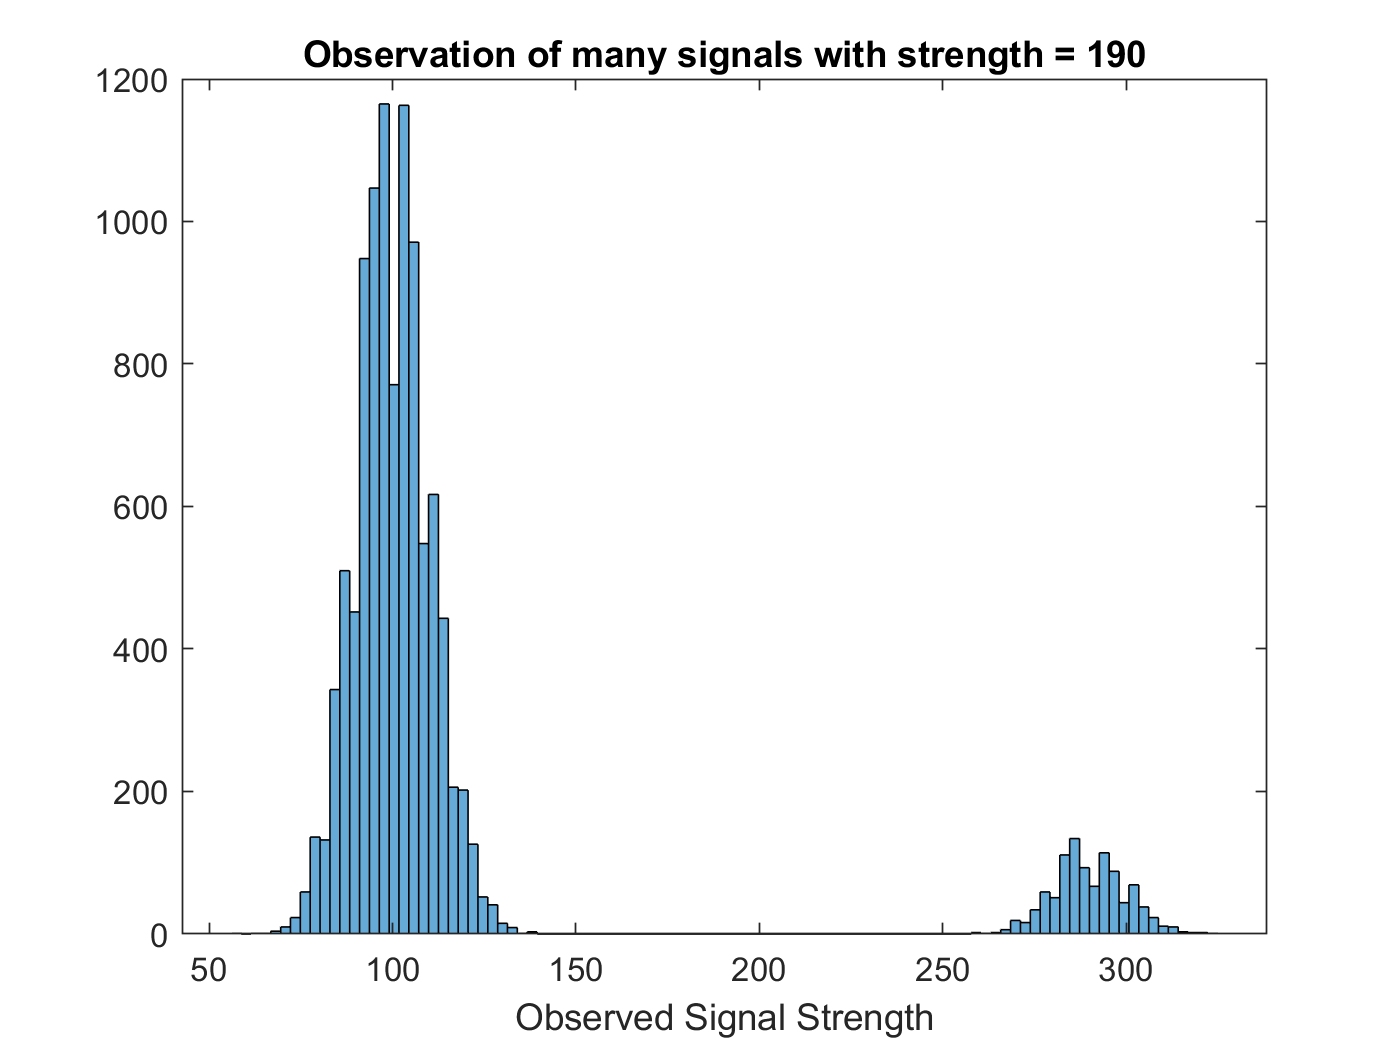

index=randi([1,size],1,1000);
noise=background(index);
signal_inj=190.*ones(1,1000)+noise;
observ_signal = [background signal_inj] ;
histogram(observ_signal,100)
title("Observation of many signals with strength = 190")
xlabel("Observed Signal Strength")

The observed signal seems to have a small range of brighter sginals around 8$\sigma$ range, as there shoud be with our interjected data. The shape still looks Poisson distributed just less counts. 

From this histogram we can see that most of the data is still around 100, because it is our background, we can also see the affect of injecting signlas into our background at random, we have a small poisson like distribution centered around 290, which is unexcpected we would want the injected signals to be around 190. 

**b) Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?**

Yes, when we added an jnjected 8 sigma signal of 190, we would expected the obersved signal to be distributed around 190, but instead it is distributed around 290. This is a bias signal because the observed signal does not hve a mean that matches the injected signal. 

## Problem 3

**Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more). **

**a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal**

*I will now make a suite of injected from, as found earlier in the lab, matlab has a certain percision and we cannot calcualte higher than 8*$\sigma$ *therefore my range for the suite of injected signals will be 0 --> 500, and I will inject 1000 signals in this range,  we know 190 is 8*$\sigma$ *so 500 is many sigma away, hopefully being around 30*$\sigma$away. 

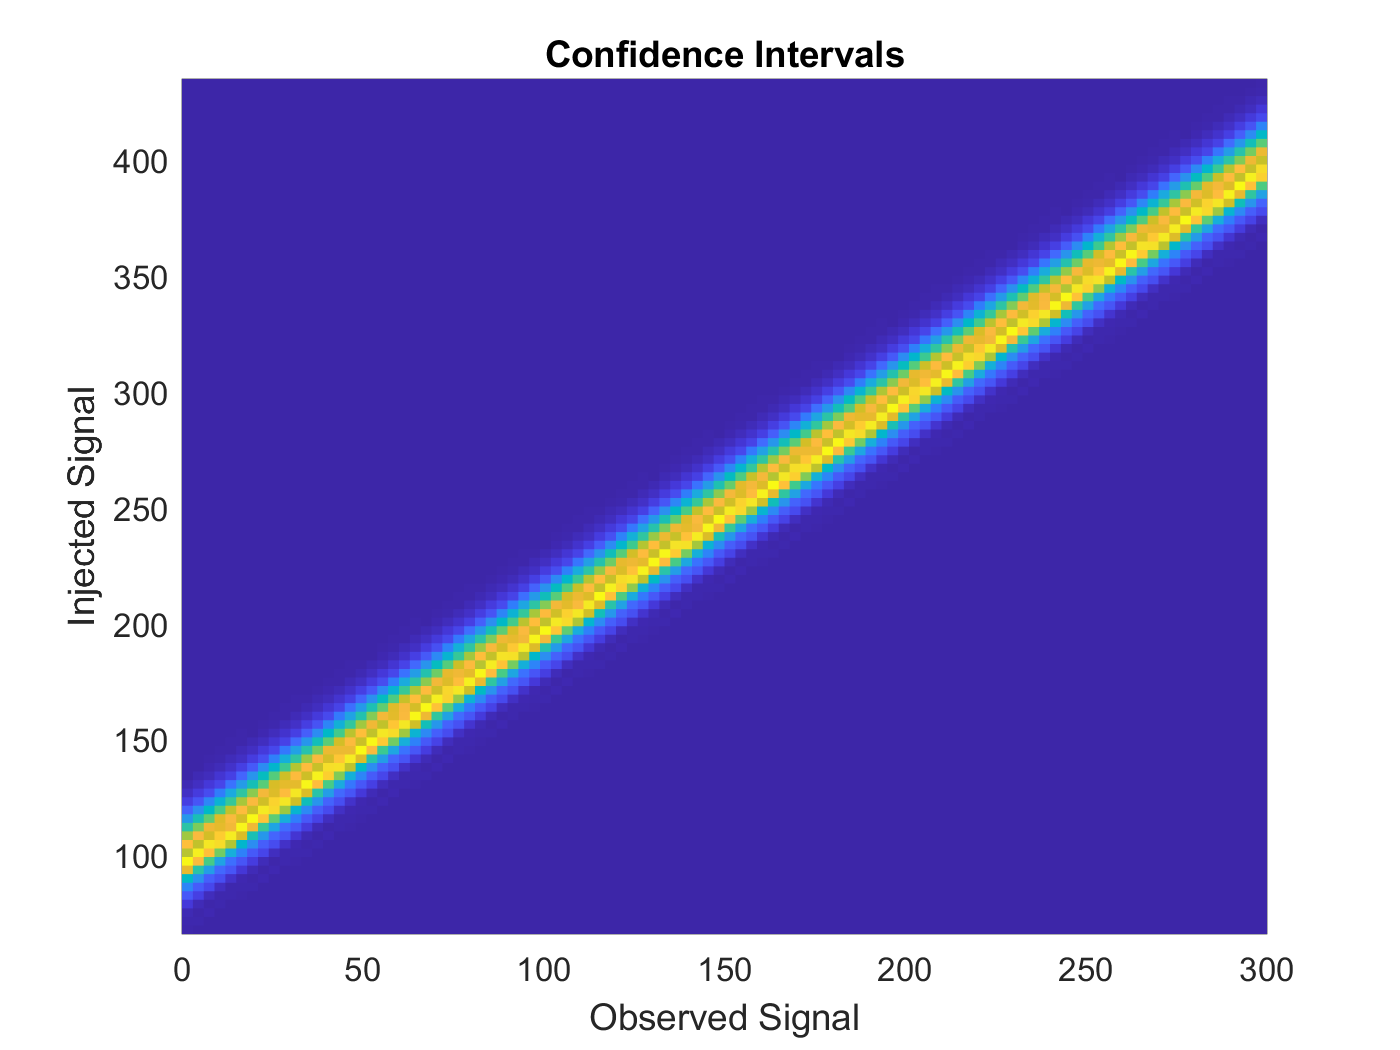

signalstrength = linspace(0,300,1000);
[scratch, signal] = meshgrid(signalstrength);

noise=repmat(background(index),1000,1);
obssignal=noise+signal;

histogram2(signal,obssignal,100,'DisplayStyle','tile','ShowEmptyBins','on');
ylabel("Injected Signal")
xlabel("Observed Signal")
title("Confidence Intervals")

The yellow band is the uncertainty of the measurement, therefore there are two things we should look at when reviewing this graph and they both pretain to the width of the yellow band. The width can tell us that if we know the value of the true signal that we are observing, then we can find the range of the signal we can measure on our detector; and if we observed a signal on our detector, we can find what is the range of the true signal. 

**b) If you choose the same injected signal power as in problem 2, show that you get the same answer.**

*If the signal strength equals 190, then what is that in the idex of the signal, coding that *

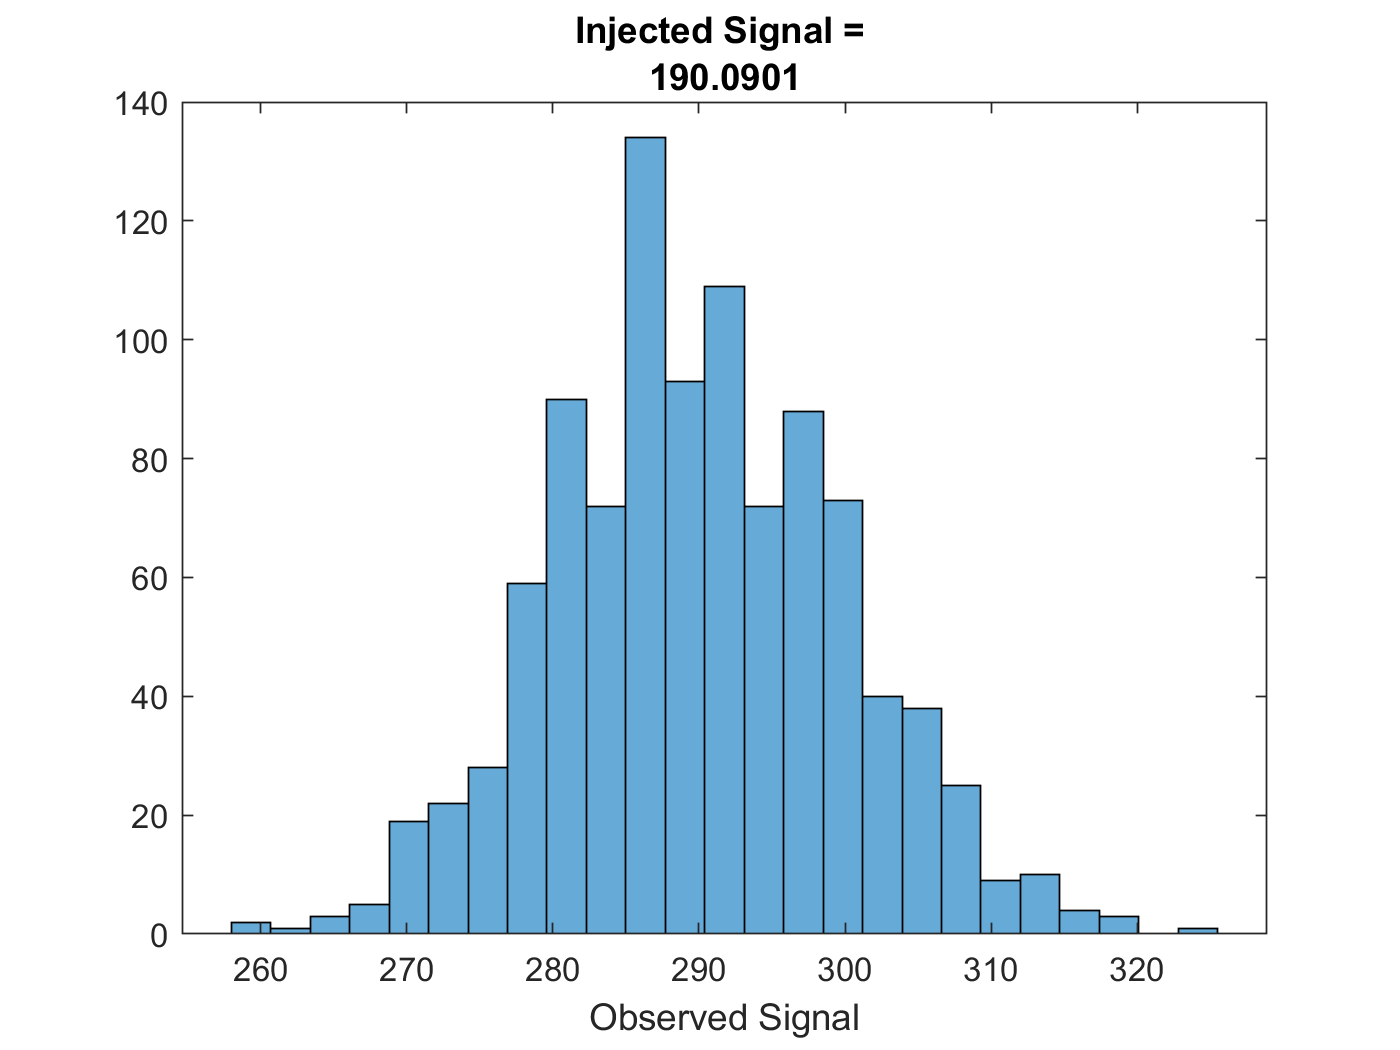

figure()
index=634; %found by guess and check to get the injected code 
signal(index);
histogram(obssignal(index,:),25)
title(["Injected Signal = ",num2str(signal(index))])
xlabel("Observed Signal")

This shows us that even when we inject from a range of sigmas or just one specific sigma (8sigma) we will still get the same distribution centered around 290, which will be a bias observed signal because our true signal and distribution should be centered around 190 not 290. This is most likely due to the backround having a strong affect on the ture signals that we are interjecting. 

**c) Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.**

*I chose the observed signal to be 290, so I can see how the problem b looks reveresed, seeing as we got the distribution to be centered around 290. *

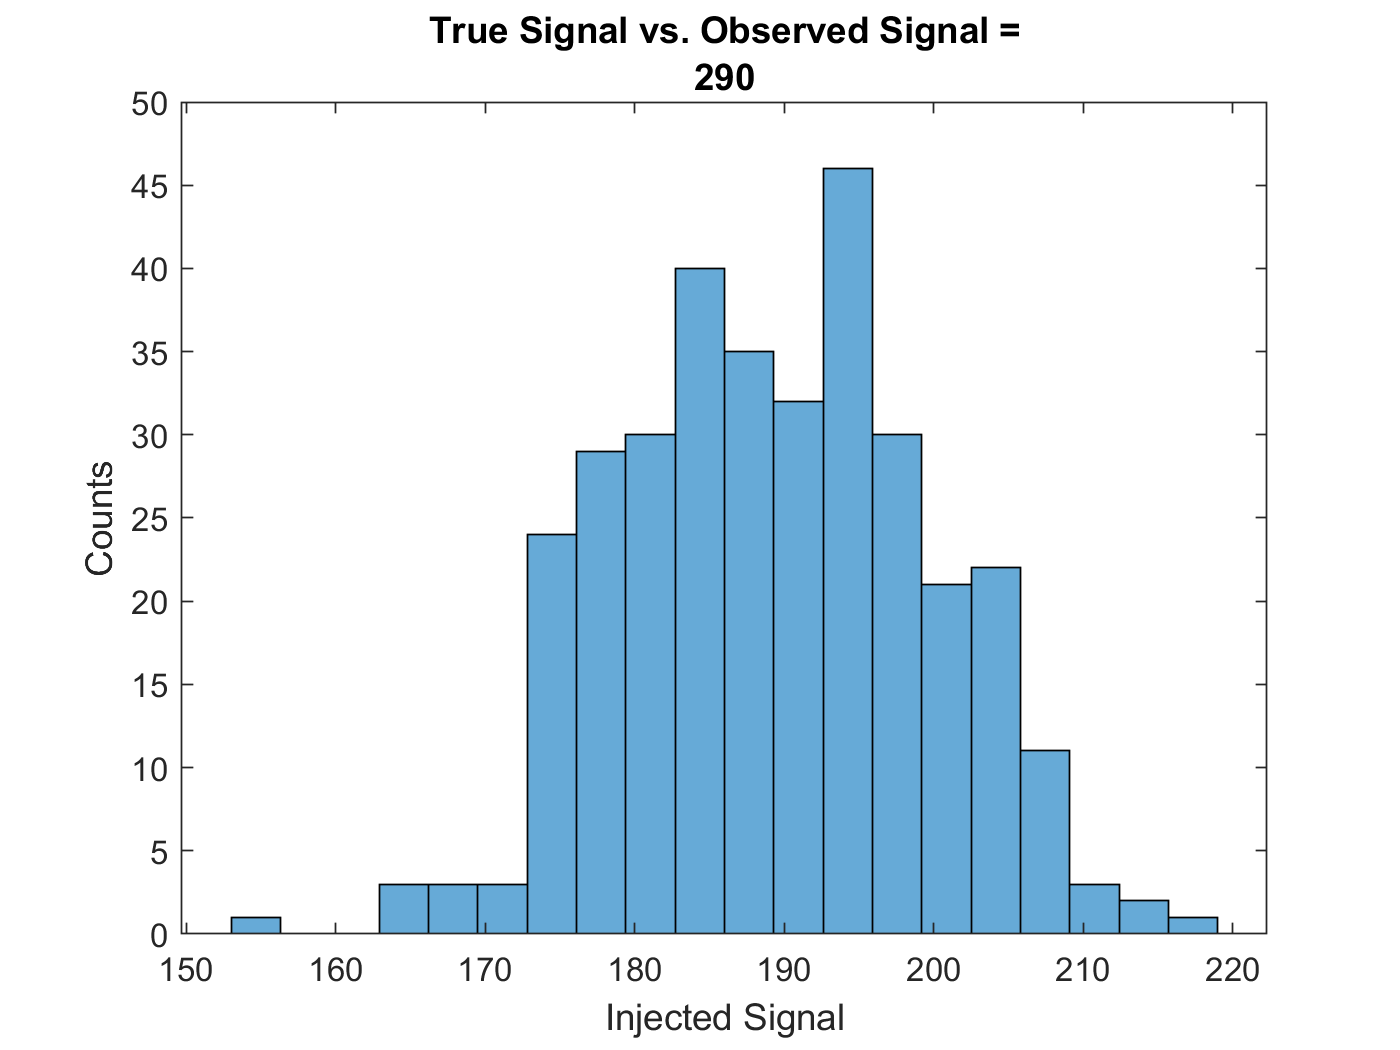

observation = 290;
injected = signal(abs(obssignal-observation)<0.05);
histogram(injected,20)
title(["True Signal vs. Observed Signal =", num2str(observation)])
xlabel("Injected Signal")
ylabel("Counts")

From what I see, my observed signal is 290, but now my injected signal are distributed around 190, which is what I originally put it, which is strange, working backwards seems to have fixed my problem. 

**d) For your observed signal, what is the 1σ uncertainty on the true signal strength?**

*To find this I will take the true signal strength to be 190, and find what the 1*$\sigma$*is. *

*We know in a Guassian Distribution, the probability of get a 1 sigma uncertainty away from the mean is 33% so below is the code to find the x vaules at the upper and lower bounds. Note that if we find the upper and the lower bounds the probability will be 66% to find the true signal *

prob=fitdist(injected,"Poisson");
lambda=190;
p_mean=cdf(prob,lambda);
low=icdf(prob,p_mean-0.33)

low = 178

up=icdf(prob,p_mean+0.33)

up = 205

 The 1σ uncertainty on the true signal strength from the lower bound is 178, and the upper bound is 204.

**e) Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?**

With this my lower bound is 178 and my upper bound is 204, and both are 1 sigma of uncertainty from my mean of 190. Seeing as we start with a Poisson distribution and it was not symmetric it would make sense that our bounds are not symmetric either, with the ture signal range distributed heavier on the right side. 

**Problem 4**

**Using the same setup as in problem 3, now pick a relatively weak signal (say in the 1σ range, exact strength not important).**

*The code below finds the 1sigma of the orginial background. *

prob1sigma_4=1-normcdf(1);
sigma_1_4=icdf(prob,1-prob1sigma_4);

1 sigma is 110, which is a relatively weak signal 

**a) Repeat problem 3c, calculating the injected signal pdf(). One of the differences you should immediately see is that the pdf() extends to zero.**

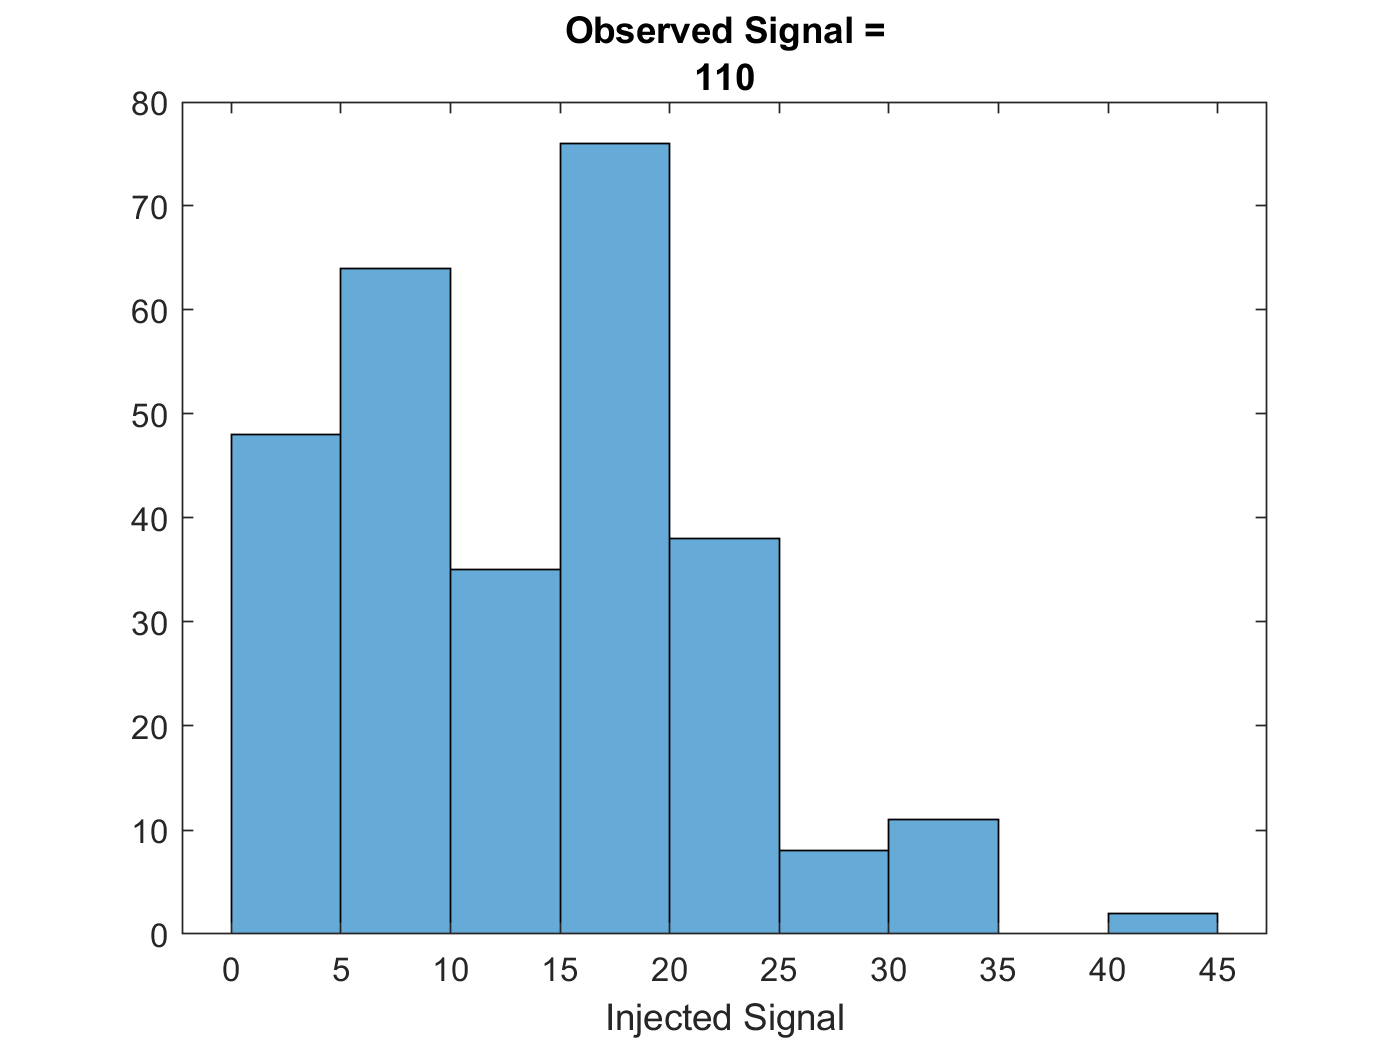

observation4=110;
injected = signal(abs(obssignal-observation4)<0.05);
histogram(injected)
title(["Observed Signal =", num2str(observation4)])
xlabel("Injected Signal")

**b) Describe what it means to have the true signal pdf() extend to zero.**

Due to the histogram extending to zero, we can assume that if we observe a signal that has a weak strength of 110, it is possible that we are not observing a true signal at all. 

**c) Calculate a 95% confidence upper bound. [Hints: make sure your pdf() is normalized. The statistical question is:  if I observe this candidate signal (and it is too weak to claim a detection), then the true signal would be less than *****X***** 95% of the time.]**

*The code below helps me to find the 95% confidence upper bound. When we look at our orginal background, in problem one we see that there is a very low chance of getting 80 as our observed signal, so it would be impossible to find the true signal if the observed signal is smaller than 80. *

observation = linspace(80,300,1000);
for i = 1:length(observation)
    threshold = 2*0.05;
    if threshold<=0.05
        break
    else
        injected = signal(abs(obssignal-observation(i))<0.05);
        pd = fitdist(injected,'Poisson');
        P = cdf(pd,observation(i));
        threshold = abs(P-0.95);
        X = observation(i);
    end
    
end

With this, knowledge we know that our background is super strong and has a mean of 100, which effects the true signal data, therefore, from this code, the probability of the true signal to be smaller than an observed signal of strength 80 is basically impossible. From this we can say with 95% confidence that the upper bound is 80. 